# **ACM/IDS 104 - Problem Set 6 - MATLAB Solutions**

*Before writing your MATLAB code, it is always good practice to get rid of any leftover variables and figures from previous scripts.*

clc; clear; close all;

***NOTE:*** Start with Problem 1, at the *bottom of this livescript*. (It's at the bottom because it's a MATLAB live function)

## Problem 2 (10 points) Ranking US Airports using PageRank

The PageRank algorithm can be used for ranking not only web pages, but any "entities'' organized into a network. The $\texttt{USAirTransportation.mat}$ file contains the adjacency matrix $A$ for the network of (anonymized) US airports: nodes represent airports and links represent air travel connections among them. That is, airports $i$ and $j$ are connected $\left(A_{ij}=1\right)$ if there are direct flights between them. The network in $\texttt{USAirTransportation.mat}$ is obtained by considering the 500 US airports with the largest amount of traffic from [publicly available data](https://toreopsahl.com/datasets/#usairports). Implement the PageRank algorithm (see lecture 12) for ranking the airports. Use your function from Problem 1 for finding the importance score vector. What are the ID numbers of 10 most important airports for $\alpha = 0.10, 0.15, 0.20$? 

Functions that may be useful for this problem:


$$\texttt{repmat(), sort(), disp(), strcat(), num2str()}$$


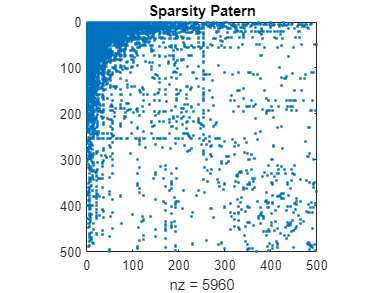

load USAirTransportation.mat % dataset
%{
Let us see how matrix A looks like
%}
figure;
spy(A);
title('Sparsity Patern');

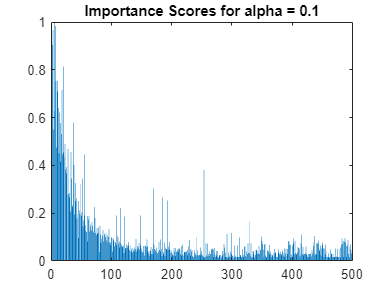

The Top 10 airports for alpha = 0.1


     6
     1
     7
     3
     2
    21
    11
     8
    18
    10



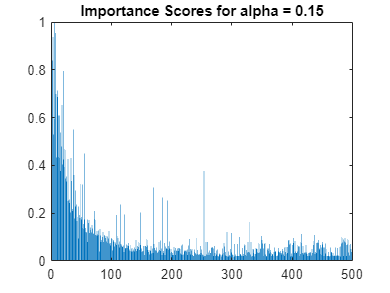

The Top 10 airports for alpha = 0.15


     6
     7
     3
     1
     2
    21
    11
     8
    10
    18



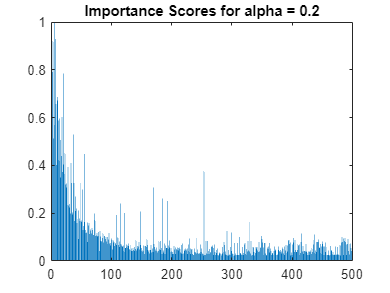

The Top 10 airports for alpha = 0.2


     6
     7
     3
     1
     2
    21
    11
    10
     8
    18



alpha = [0.10 0.15 0.20]; % values of alpha
[~,n]=size(A); % size of A
%{
Implement the algorithm below
You can use bar() to visualize the scores
Report the top 10 airports (in descending order) for each alpha
%}
L=A./repmat(sum(A),n,1);  % link matrix
for i = alpha
LL=(1-i)*L+i*repmat(ones(1,n)/n,n,1); % LL is \tilde{L}
[lambda,x]=power_method(LL);   
% lambda must be 1, v is the eigenvector of importance scores
figure;
bar(x);
title(strcat("Importance Scores for alpha = ", num2str(i)));
[x,ind]=sort(x,'descend');
disp(strcat("The Top 10 airports for alpha = ", num2str(i)));
disp(ind(1:10));
end

## Problem 4 (10 points) Principal Component Analysis

In this problem, you will find the principal components of the dataset $\texttt{pca\_data.mat}$, which contains the $m\times n$ matrix $X$. Columns of $X$ correspond to $n=10^4$ measurements and rows of $X$ correspond to $m=2$ quantities (features). Let us see what the data looks like:

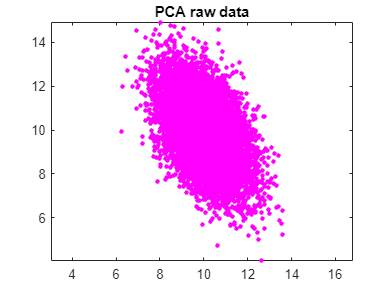

load pca_data.mat
figure;
plot(X(1,:),X(2,:),'.m','MarkerSize',10);
title("PCA raw data");
axis equal

### Part (a)

Find the $m\times m$ covariance matrix of $X$. Use $\texttt{disp()}$ to display it.

[m, n] = size(X); % m = # measurement types (features); n = # of measurements
for i = 1 : m
    mu(i) = mean(X(i, :));
    Xn(i, :) = X(i, :) - mu(i); % normalization 
end
Cx = Xn*Xn'/n; % Covariance matrix
%{ 
Or, equivelantly:
Cx=cov(X');  % formula in line 32 is valid only if row means are zero.
%}
disp("The covariance matrix of X is:");

The covariance matrix of X is:


disp(Cx);

    0.9829   -0.6808
   -0.6808    1.9508



### Part (b)

Find the $m$ principal components of $X$ and show them on top of the original data. That is, if $v$ is a principal component, then plot the line $l(t) = \mu+vt$ over the scatter plot shown above, where $\mu\in\mathbb{R}^2$ is the centroid of the data.

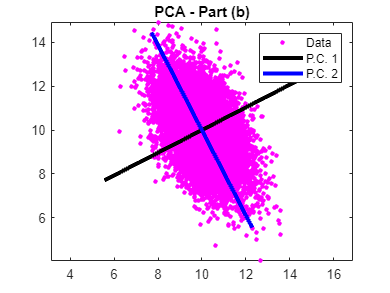

%{
Find the eigenvectors
Normalize
Obtain the centroids
Create the lines
Plot
%}
[V1, D] = eig(Cx); % finding eigenstuff
v_1 = V1(:, 1); % eigenvector 1
v_1 = v_1 / norm(v_1); % normalize
v_2 = V1(:, 2); % eigenvector 2
v_2 = v_2 / norm(v_2); % normalize
c_1 = mu(1); % centroid 1
c_2 = mu(2); % centroid 2
p_1 = @(t) c_1 + v_1(1) * t; % get x^1 coord. for point p
q_1 = @(t) c_2 + v_2(1) * t; % get x^1 coord. for point q
p_2 = @(t) c_1 + v_1(2) * t; % get x^2 coord. for point p
q_2 = @(t) c_2 + v_2(2) * t; % get x^2 coord. for point q
% PLOT
plot(X(1,:),X(2,:),'.m','MarkerSize',10);
hold on
fplot(p_1, p_2, "-k", "lineWidth", 3);
fplot(q_1, q_2, "-b", "lineWidth", 3);
title("PCA - Part (b)");
legend("Data","P.C. 1", "P.C. 2");
axis equal

### Part (c)

If we change the basis of $\mathbb{R}^m$ from the standard basis to the basis of the principal components $[v_1,\cdots,v_m] = V$ of $X$, the data matrix will transform to $Y = V^{-1}X$. Find the covariance of the transformed data $Y$. Use $\texttt{disp()}$ to display it.

Y = V1'*X;
for i = 1 : m
    Yn(i,:) = Y(i,:)-mean(Y(i,:)); % normalizatoin 
end
Cy = Yn*Yn'/n; % = Lambda
%{ 
Or, equivelantly:
Cy=cov(Y'); % formula in line 61 is valid only of row means are zero.
%}
disp("The covariance matrix of the transformed data Y is:");

The covariance matrix of the transformed data Y is:


disp(Cy);

    0.6316    0.0000
    0.0000    2.3021



### Part (d)

Principal component analysis is a very popular data analysis technique and it is often used in various applications. As such, it is implemented in most numerical software packages. In MATLAB, this is a built-in function $\texttt{pca()}$. In the simplest form, $\texttt{V = pca(X)}$ returns the principal components of the data matrix $X$, where rows of $X$ correspond to the *measurements* and columns correspond to the *features*. Find the principal components of $X$ using $\texttt{pca()}$ and compare them with the ones found in part (b). Are they the same?

V2 = pca(X');
disp("Found in part (b):");

Found in part (b):


disp(V1);

   -0.8886   -0.4586
   -0.4586    0.8886



disp("Using pca():");

Using pca():


disp(V2);

   -0.4586    0.8886
    0.8886    0.4586



disp("The vectors agree!");

The vectors agree!


## Problem 5 (10 points) Spectral Method for Graph Partitioning

A complete graph $K_n$ with $n$ vertices is a graph in which each pair of graph vertices is connected by an edge. Let $G$ be a barbell-like graph obtained by connecting $K_{n_1}$ and $K_{n_2}$ with $m=3$ bridges, where $n_1=20$ and $n_2=30$. The graph $G$ and the sparsity pattern of its adjacency matrix are shown:

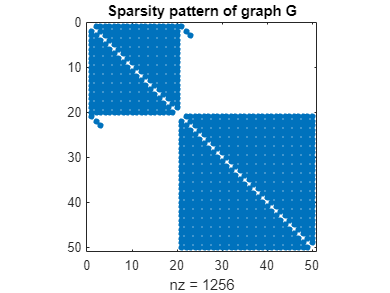

%{
Adjacency matrix
%}
n1=20; 
n2=30;
B1=ones(n1,n1)-diag(ones(1,n1));
B2=ones(n2,n2)-diag(ones(1,n2));
B=[B1, zeros(n1,n2);zeros(n2,n1), B2]; % adjacency matrix B of graph G
for i=1:3
    B(i,n1+i)=1; B(n1+i,i)=1; % bridges
end
%{
Visualization
%}
figure;
spy(B);
title("Sparsity pattern of graph G");

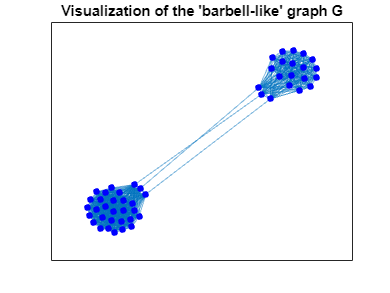

figure;
G = graph(B);
plot(G,'NodeLabel',{},'NodeColor','b');
title("Visualization of the 'barbell-like' graph G");

Use the spectral partitioning method to find a division of the graph $G$ into two subgraphs of size $n_1=20$ and $n_2=30$ such that the number of edges between the subgraphs (the cut size) is minimized. Visualize the obtained partition and find the corresponding cut size. Useful functions for this problem:


$$\texttt{eigs(), find(), highlight(), plot()}$$


%{
-> Find the graph Laplacian
-> Find the Fiedler vector
-> Determine the 2 candidate partitions
-> Visualize
-> Report the cut size using disp()
%}

% LAPLACIAN & FIEDLER VECTOR
La = diag(sum(B))-B;  % or simply La=laplacian(G)
[V,Lambda] = eigs(La,2,'sm'); % two smallest eigenvalues and 

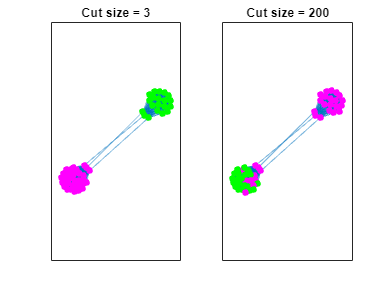

                              % the corresponding eigenvectors
v2=V(:,2); % the Fiedler vector (corresponds to the 2nd smallest eigenvalue)

% PARTITIONS
[~,ind]=sort(v2);
Sp=-ones(n1+n2,1);    
Sp(ind(n2+1:end))=1; % s "plus"
Rp=Sp'*La*Sp/4; % the corresponding cut size
Sm=-ones(n1+n2,1);    
Sm(ind(1:n1))=1; % s "minus"
Rm=Sm'*La*Sm/4; % the corresponding cut size

% VISUALIZATION
figure;
subplot(1,2,1);  % partion Sp
h=plot(G,'NodeLabel',{});  % Graph G 
highlight(h,find(Sp>0),'NodeColor','g'); % subgraph 1
highlight(h,find(Sp<0),'NodeColor','m'); % subgraph 2
title(strcat("Cut size = ", num2str(Rp)));
axis equal
subplot(1,2,2);   % partition Sm
h=plot(G,'NodeLabel',{});  % Graph G
highlight(h,find(Sm>0),'NodeColor','g'); % subgraph 1
highlight(h,find(Sm<0),'NodeColor','m'); % subgraph 2
title(strcat("Cut size = ", num2str(Rm)));
axis equal


% REPORTING CUT SIZE
disp(strcat("The minimum cut size is ", num2str(Rp)));

The minimum cut size is 3


## Problem 1 (10 points) - The Power Method (aka Von Mises Iteration)

Let $A$ be an $n\times n$ matrix with eigenvalues $\lambda_1,\cdots,\lambda_n$ such that:


$$|\lambda_1|>|\lambda_2|>\cdots>|\lambda_n|$$


The eigenvalue $\lambda_1$ is called the dominant eigenvalue and the corresponding eigenvector $v_1$ is called the dominant eigenvector. Write a function that takes $A$ as an argument and uses the Power method (Lecture 12) to compute $\lambda_1$ and $v_1$. We can check that $\lambda_1$ is correct by comparing it with the $\texttt{eig()}$ function for a random matrix. An example is provided below:

%{
E = [9,8,7;6,5,4;3,2,1];
[b, d] = eig(E);
[J, VE] = power_method(E);
disp(d(1));
disp(J);
%}

function [lambda, v] = power_method(A)
[n, ~] = size(A); % size of nxn matrix A
v_prev = rand(n, 1); % random starting vector
tol = Inf; % relative error
%{
Implement the algorithm in the while loop
%}
while tol > 1e-15
    v = A * v_prev;
    lambda = norm(v, Inf);
    v = v / lambda;
    tol = norm(v - v_prev, Inf)/norm(v_prev, Inf);
    v_prev = v;
end
end